% a clear MATLAB workspace is a clear mental workspace
close all; clear

## create data for the plot

% number of data points
n = 1000;

% generate log-normal distribution
data1 = exp( randn(n,1)/2 );
data2 = exp( randn(n,1)/10 );
data3 = exp( randn(n,1)/2 + 1 );

## histograms on top of each other

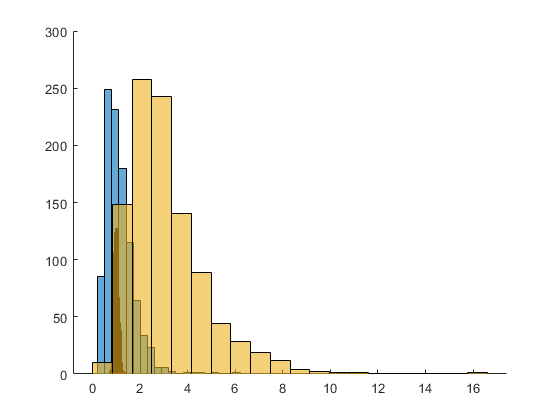

% number of histogram bins
k = 20;

figure(1), clf, hold on
histogram(data1,k)
histogram(data2,k)
histogram(data3,k)

## plots of their histograms

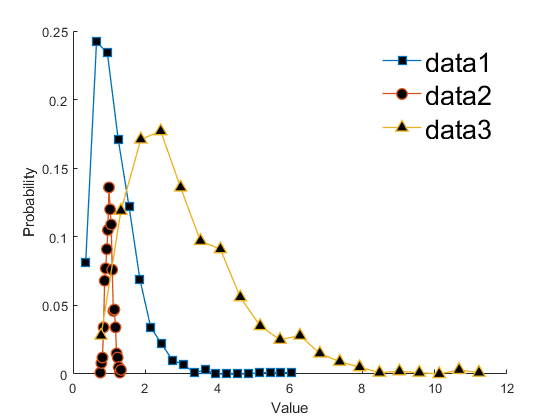

% histogram discretization for the datasets
[y1,x1] = histcounts(data1,k);
xx1 = (x1(1:end-1) + x1(2:end)) / 2;
y1 = y1 / sum(y1); % convert to probability

[y2,x2] = histcounts(data2,k);
xx2 = (x2(1:end-1) + x2(2:end)) / 2;
y2 = y2 / sum(y2); % convert to probability

[y3,x3] = histcounts(data3,k);
xx3 = (x3(1:end-1) + x3(2:end)) / 2;
y3 = y3 / sum(y3); % convert to probability


figure(2), clf, hold on
plot(xx1,y1,'s-','linew',1,'markersize',8,'markerfacecolor','k')
plot(xx2,y2,'o-','linew',1,'markersize',8,'markerfacecolor','k')
plot(xx3,y3,'^-','linew',1,'markersize',8,'markerfacecolor','k')
xlabel('Value')
ylabel('Probability')
legend({'data1';'data2';'data3'},'box','off','fontsize',20)

## done.